# Estudio de separabilidad de un punto

En este script vamos a tratar de determinar en base a un ejemplo lo siguiente. Tomamos $N$ puntos aleatorios en $B(0,1)$, de los cuales elegimos uno arbitrario, llamémosle de clase A y a los demás de clase B. ¿Cómo hay que elegir una recta plana (en general será un hiperplano en dimensión $n$) de froma que haya el menor número de puntos posible de clase B en la sección del plano en la que se encuentra el punto de clase A?

Comenzamos definiendo la bola como

    $(\rho, \theta) \rightarrow \rho (\cos\theta, \sin\theta) : \rho \in [0, 1), \theta \in [0, 2\pi)$.

## Separabilidad de 2 puntos

Empecemos con tan sólo dos puntos y veamos cómo evoluciona la probabilidad de separarlos.

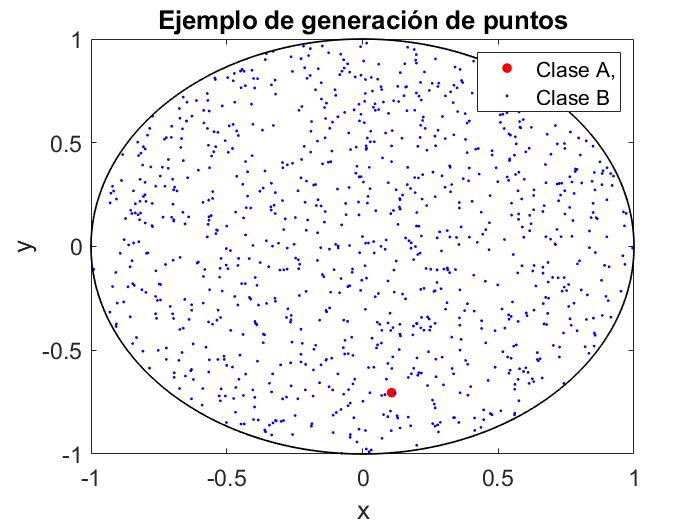

[X, Y] = generatePoints(1000, 2, 1);

max(vecnorm(X, 2, 2));

% Dibujamos los puntos generados
plotPoints(X, Y, 'Ejemplo de generación de puntos');
legend({'Clase A,', 'Clase B'});
hold off

Empezamos tomando un hiperplano (una recta en este caso) perpendicular al vector $\overrightarrow{x_1}$, suponiendo que sea $x_1$ el de clase A, a distancia $\theta \in (0, \|\overrightarrow{x_1}\|)$ del origen. Entonces, dicho hiperplano será $H = \overrightarrow{H} + \theta \frac{\overrightarrow{x_1}}{\|\overrightarrow{x_1}\|}$, donde $\overrightarrow{H} \equiv \overrightarrow{x_1} x = 0$.

En cualquier caso, lo que nos interesará será la distancia $\theta$.

Ahora, definamos $A$ como el espacio que queda comprendido "por encima" de $H$, dentro de la bola.

Podemos calcular la probabilidad de que los dos puntos hayan quedado separados de la siguiente forma:

$P(\text{sep}(x_1, x_2)) = 1 - \frac{V(A)}{V(B_n(0,1))}$.

El volumen de $A$ es difícil de calcular, pero podemos utulizar el hecho de que sabemos que es menor o igual que el de una bola de radio $r = \sqrt{1 - \theta^2}$, por Pitágoras. Así,

$P(\text{sep}(x_1, x_2) \geq 1 - \frac{\frac{1}{2}V(B_n(0, r))}{V(B_n(0, 1))}$.

Por otro lado, sabemos (buscar demostración) que $V(B_n(0, r)) =
\frac{1}{2}
\frac{\pi^{n/2}}{\Gamma\Big(\frac{n}{2} + 1\Big)} r^n$.

Por tanto, $P(\text{sep}(x_1, x_2)) \geq 1 - \frac{1}{2} r^n$.

Vamos a calcular empíricamente la probabildad de que dos puntos queden separados por el hiperplano descrito en diferentes dimensiones. Elegiremos $\theta = \|\overrightarrow{x_1}\| - \varepsilon$ para cierto $\varepsilon > 0$.

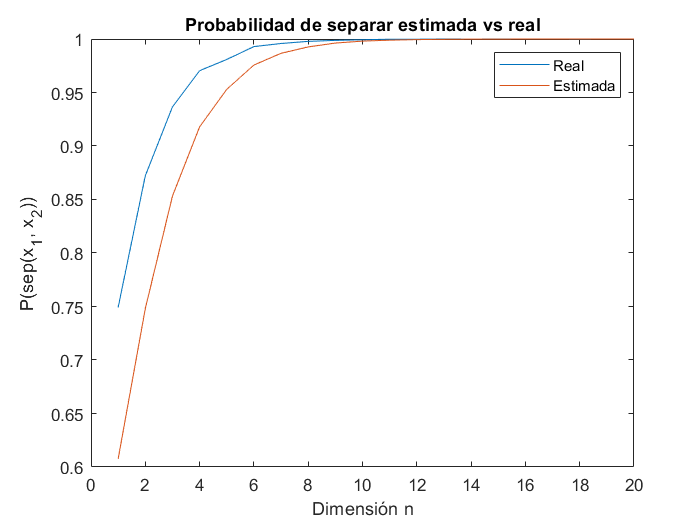

ns = 1:20;
N = 2;
M = 10000;

estimatedPs = zeros(1, size(ns, 1));
realPs = zeros(1, size(ns, 1));

for n = ns
    estimatedP = 0;
    realP = 0;
    for m = 1:M
        [X, Y] = generatePoints(N, n, 1);
        x1 = X(Y == 1, :);
        x2 = X(Y == -1, :);
        
        theta = norm(x1) - eps;
        p = theta * x1 / norm(x1);
        % Plano normal a x1 que pasa por p
        H = @(x) dot(x1, x - p);
        realP = realP + (sign(H(x1)) ~= sign(H(x2)));
        
        r = sqrt(1 - theta^2);
        estimatedP = estimatedP + 1 - 1/2 * r^n;
    end
    
    estimatedPs(n) = estimatedP / M;
    realPs(n) = realP / M;
end

figure
plot(realPs);
hold on
plot(estimatedPs);
title('Probabilidad de separar estimada vs real');
xlabel('Dimensión n');
ylabel('P(sep(x_1, x_2))');
legend({'Real', 'Estimada'});
hold off

function X = randsphere(m, n, r)
    % https://es.mathworks.com/matlabcentral/fileexchange/9443-random-points-in-an-n-dimensional-hypersphere
    X = randn(m, n);
    s2 = sum(X.^2, 2);
    X = X.* repmat(r * (gammainc(s2/2, n/2).^ (1/n))./ sqrt(s2), 1, n);
end

function [X, Y] = generatePoints(N, n, A)
    X = randsphere(N, n, 1);
    Y = ones(N, 1);
    indices = randsample(N, N - A);
    Y(indices) = -1;
end

function plotPoints(X, Y, titleText)
    ball = @(rho, theta) [rho.* cos(theta); rho.* sin(theta)];
    frontier = @(theta) ball(1, theta);
    
    plotThetas = linspace(0, 2 * pi, 1000);
    plotFrontier = frontier(plotThetas);
    
    A = Y == 1;
    
    figure
    % Punto de clase A
    plot(X(A, 1), X(A, 2), 'r.', 'MarkerSize', 20);
    hold on
    plot(X(~A, 1), X(~A, 2), 'b.', 'MarkerSize', 5);
    plot(plotFrontier(1, :), plotFrontier(2, :), 'LineWidth', 1, ...
        'Color', 'k', 'HandleVisibility', 'off');
    set(gca, 'FontSize', 14);
    title(titleText);
    xlabel('x');
    ylabel('y');
end